# Measuring the Quality of Processed Images

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

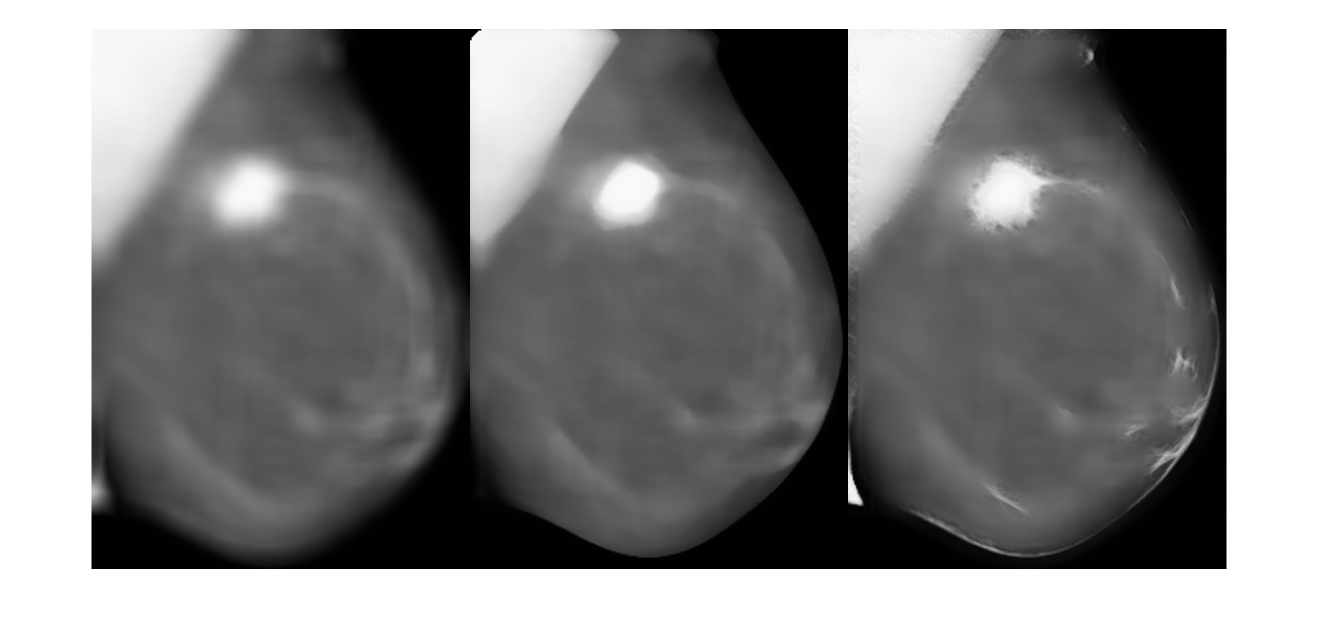

tumor = readmatrix("./images/tumorReducedSize.csv", OutputType="uint8");
tumorAvg = imfilter(tumor, fspecial("average", [15 15]), "symmetric");
tumorMed = medfilt2(tumor, [15 15]);
tumorW = wiener2(tumor, [15 15]);
montage({tumorAvg tumorMed tumorW})

## Task 1

The Natural Image Quality Evaluator (NIQE) can measure the quality of images with arbitrary distortion with a lower score being better. NIQE is opinion-unaware. So, it may not correlate as well as an opinion-aware score with human perception of quality.

To calculate the NIQE score, use the `niqe` function.

`score` `=` `niqe``(``I``)`

Images filtered using average linear, median, and Wiener filters are saved in variables `tumorAvg`, `tumorMed`, and `tumorW` respectively.

niqeAvg = niqe(tumorAvg)

niqeAvg = 5.4201

## Task 2

niqeMed = niqe(tumorMed)

niqeMed = 4.9832

niqeW = niqe(tumorW)

niqeW = 8.2628

## Task 3

The opinion-aware Blind/Referenceless Image Spatial Quality Evaluator, or BRISQUE, model is trained on a database of images with known distortions and subjective quality scores. The database contains images with known distortion such as compression artifacts, blurring, and noise, and it contains pristine versions of the distorted images. These medical scans struggle with the balance of blurring and noise, so this metric may be appropriate here.

To calculate the BRISQUE score, use the `brisque` function.

`score` `=` `brisque``(``I``)`

bAvg = brisque(tumorAvg)

bAvg = 58.6630

bMed = brisque(tumorMed)

bMed = 52.3520

bWien = brisque(tumorW)

bWien = 53.3746